# Lattice characterization v2, Step input behavior inspection

 Note: Open the step_input/processed_data.mat before running the script

fz_biased = fz-fz(1);
z_biased = z - z(1);

n = size(t_biased,1);

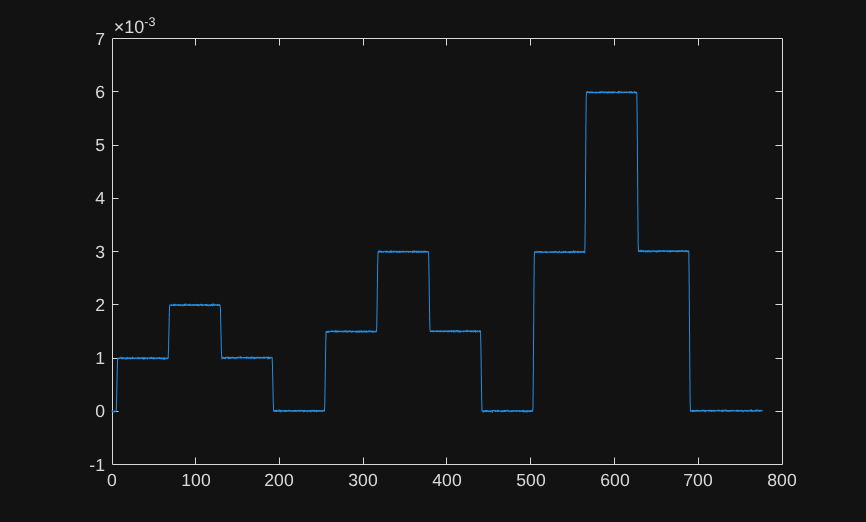

plot(t_biased,z_biased)

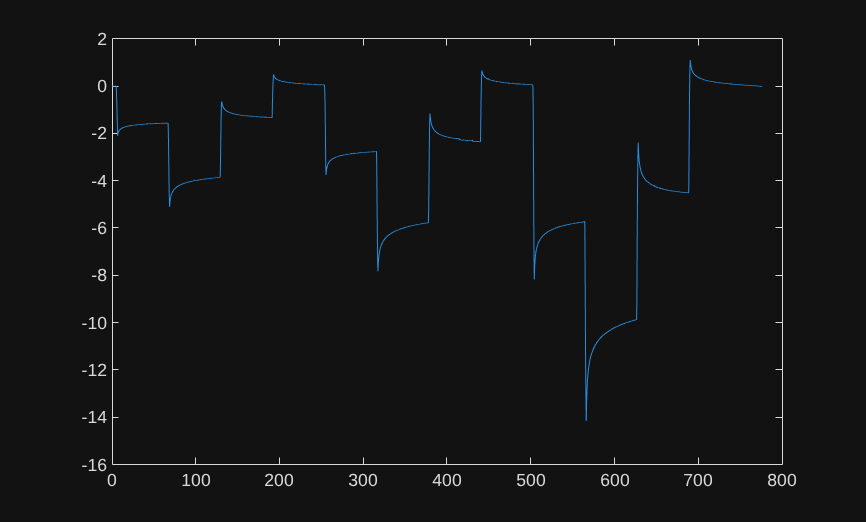

plot(t_biased,fz_biased)

t_1 = t_biased(1:25200);
z_1 = z_biased(1:25200);
fz_1 = fz_biased(1:25200);

t_2 = t_biased(25200:50075);
z_2 = z_biased(25200:50075);
fz_2 = fz_biased(25200:50075);

t_3 = t_biased(50075:75600);
z_3 = z_biased(50075:75600);
fz_3 = fz_biased(50075:75600);

% for fz, find the derivative of fz.
Dfz_1 = diff(fz_1,1);
Dfz_1 = Dfz_1/0.01;
Dfz_1 = [0.0; Dfz_1];
Dfz_1= lowpass(Dfz_1,0.1);
Dfz_2 = diff(fz_2,1);
Dfz_2 = Dfz_2/0.01;
Dfz_2 = [0.0; Dfz_2];
Dfz_2 = lowpass(Dfz_2,0.1);
Dfz_3 = diff(fz_3,1);
Dfz_3 = Dfz_3/0.01;
Dfz_3 = [0.0; Dfz_3];
Dfz_3 = lowpass(Dfz_3,0.1);

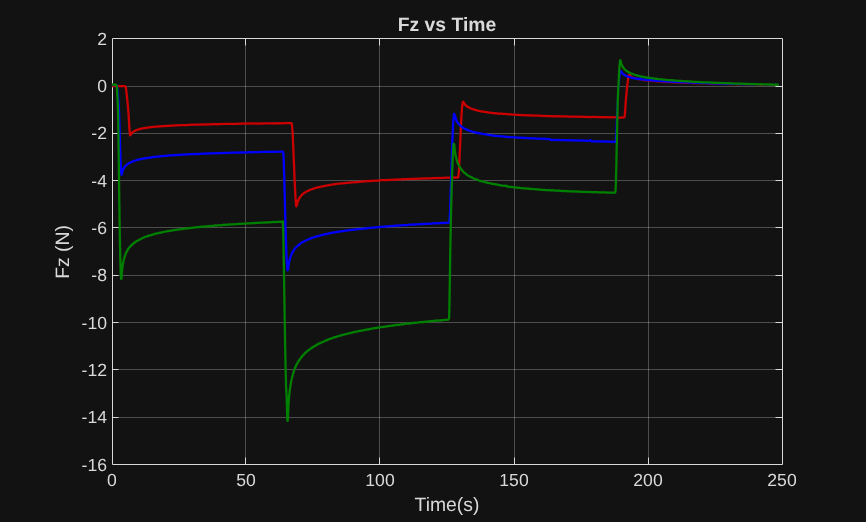

len2 = size(fz_2,1);

t_ad = 0:0.01:(len2/100);
t_ad(1) = [];

fz_1(len2+1:end) = [];
fz_3(len2+1:end) = [];

fz_plot = figure("Name","fz_plot");
figure(fz_plot);
plot(t_ad,fz_1,"Color","0.8 0 0","LineWidth",1.3);
hold on;
plot(t_ad,fz_2,"Color","0 0 1","LineWidth",1.3);
plot(t_ad,fz_3, "Color","0 0.5 0","LineWidth",1.3)

grid on;
title("Fz vs Time");
xlabel("Time(s)");
ylabel("Fz (N)");

hold off;

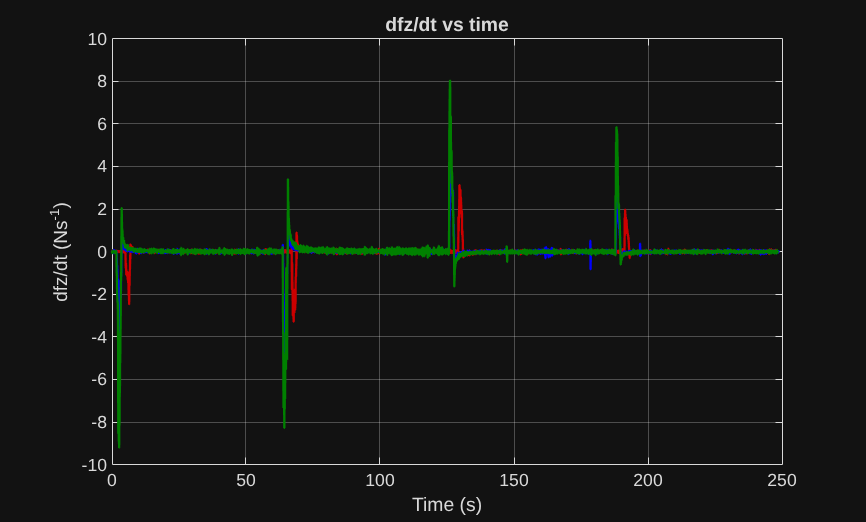

Dfz_1(len2+1:end) = [];
Dfz_3(len2+1:end) = [];

figure;
plot(t_ad, Dfz_1,"Color","0.8 0 0","LineWidth",1.3);
hold on;
plot(t_ad, Dfz_2,"Color","0 0 1","LineWidth",1.3);
plot(t_ad, Dfz_3, "Color","0 0.5 0","LineWidth",1.3)

grid on;
title("dfz/dt vs time");
xlabel("Time (s)");
ylabel("dfz/dt (Ns^{-1})")

hold off;

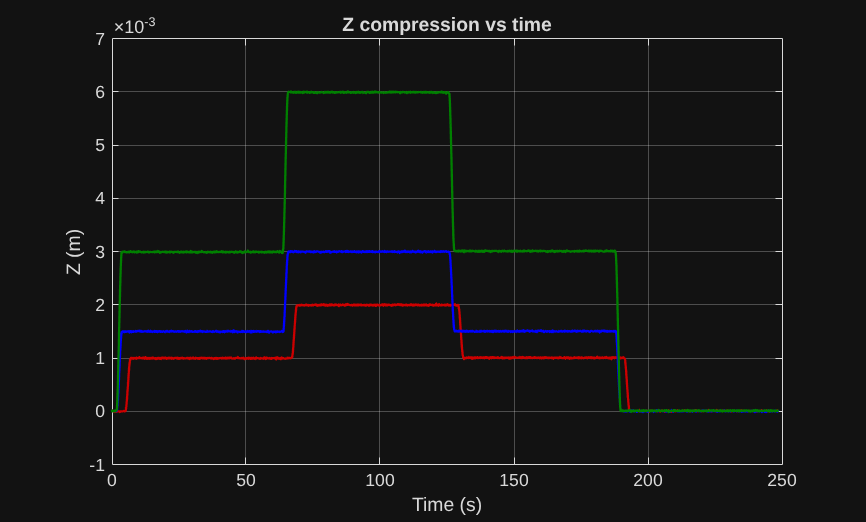

len2 = size(z_2,1);

z_1(len2+1:end) = [];
z_3(len2+1:end) = [];

figure;
plot(t_ad,z_1,"Color","0.8 0 0","LineWidth",1.3);
hold on;
plot(t_ad,z_2,"Color","0 0 1","LineWidth",1.3);
plot(t_ad,z_3, "Color","0 0.5 0","LineWidth",1.3)

grid on;
title("Z compression vs time");
xlabel("Time (s)");
ylabel("Z (m)");
hold off;

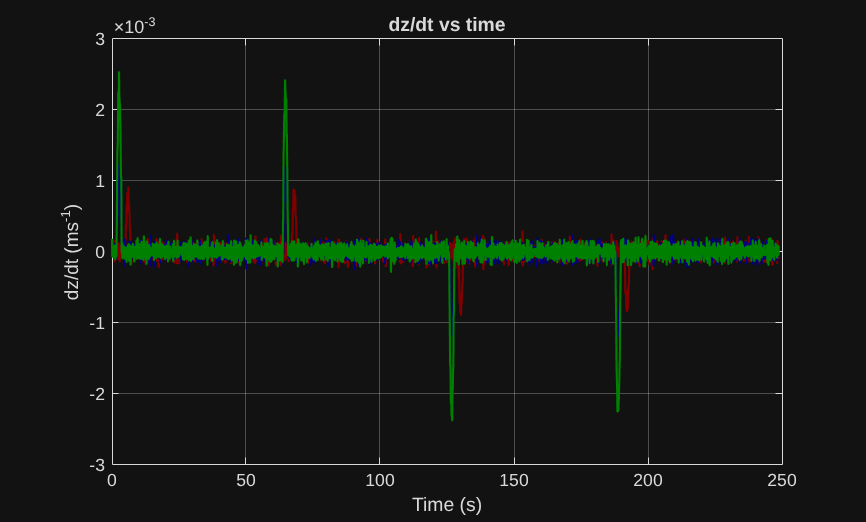

dz_1 = diff(z_1);
dz_2 = diff(z_2);
dz_3 = diff(z_3);

dz_1 = [0; dz_1];
dz_2 = [0; dz_2];
dz_3 = [0; dz_3];

dz_1 = dz_1/0.01;
dz_2 = dz_2/0.01;
dz_3 = dz_3/0.01;

dz_1 = lowpass(dz_1,0.01);
dz_2 = lowpass(dz_2,0.01);
dz_3 = lowpass(dz_3,0.01);

figure;
plot(t_ad,dz_1,"Color","0.5 0 0", "LineWidth",1.2);
hold on;
plot(t_ad,dz_2,"Color","0 0 0.5", "LineWidth",1.2);
plot(t_ad,dz_3,"Color","0.0 0.5 0", "LineWidth",1.2);
title("dz/dt vs time");
xlabel("Time (s)");
ylabel("dz/dt (ms^{-1})");
grid on;

hold off

### Relaxation slope

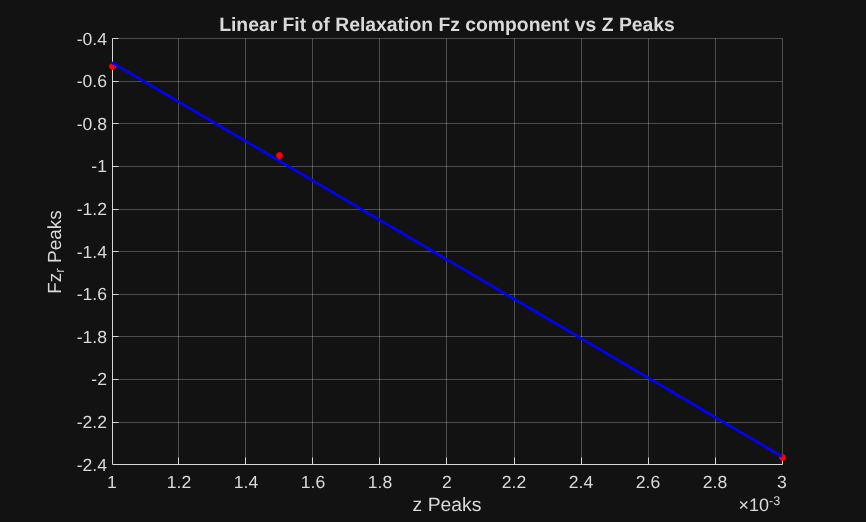

fz_r_peaks = [fz_1(688) - fz_1(6689); (fz_2(360) - fz_2(6392)); (fz_3(350) - fz_3(6379));];
z_peaks = [1e-3; 1.5e-3; 3.0e-3];
figure;
scatter(z_peaks, fz_r_peaks,15,"red","filled");
hold on;

p_relaxation = polyfit(z_peaks, fz_r_peaks, 1);
fz_r_fit = polyval(p_relaxation, z_peaks);
plot(z_peaks, fz_r_fit, 'LineWidth', 1.5, 'Color', 'blue');
xlabel('z Peaks');
ylabel('Fz_r Peaks');
title('Linear Fit of Relaxation Fz component vs Z Peaks');
grid on;
hold off;

### Elastic slope

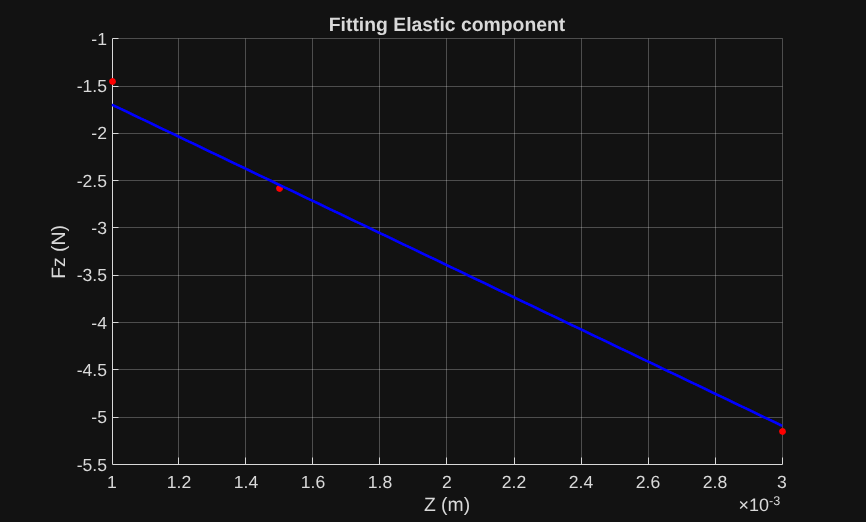

fz_e = [(fz_1(6689) + fz_1(19122))/2; (fz_2(6392) + fz_2(18783))/2; (fz_3(6379)+fz_3(18781))/2];
z_e = [1e-3; 1.5e-3; 3.0e-3];
figure;
scatter(z_e,fz_e,15,"red","filled");

k = fz_e'*z_e / ((norm(z_e))^2);

fz_e_fit = k*z_e;

hold on;
title("Fitting Elastic component");
xlabel("Z (m)");
ylabel("Fz (N)");
plot(z_e,fz_e_fit,"Color","0 0 1","LineWidth",1.5);
grid on;
hold off;

### Elastic viz

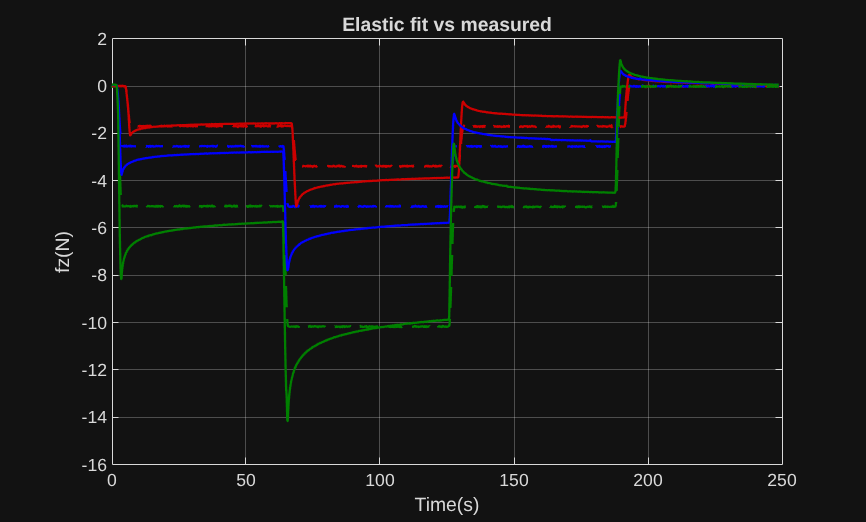

figure(fz_plot);
fz_1_e_fit = k*z_1;
fz_2_e_fit = k*z_2;
fz_3_e_fit = k*z_3;
plot(t_ad,fz_1_e_fit,"Color", "0.8 0 0","LineStyle","--","LineWidth",1.3);
hold on;
plot(t_ad,fz_2_e_fit,"Color", "0 0 1","LineStyle","--","LineWidth",1.3);
plot(t_ad,fz_3_e_fit,"Color", "0 0.5 0","LineStyle","--","LineWidth",1.3);
plot(t_ad,fz_1,"Color","0.8 0 0","LineWidth",1.3);
plot(t_ad,fz_2,"Color","0 0 1","LineWidth",1.3);
plot(t_ad,fz_3,"Color","0 0.5 0","LineWidth",1.3);
title("Elastic fit vs measured");
xlabel("Time(s)");
ylabel("fz(N)");
grid on;
hold off;

fprintf("K value : %f",k);

K value : -1696.638452

### Relaxation Component visualization

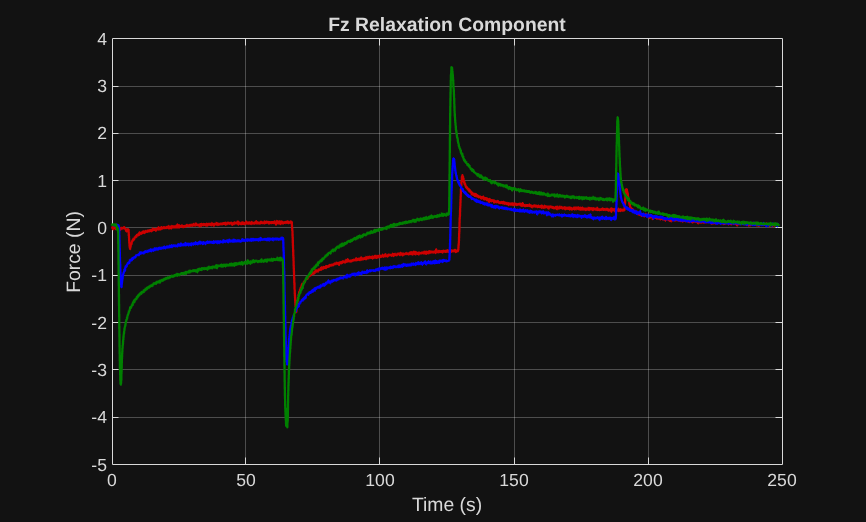

fz_r_1 = fz_1 - fz_1_e_fit;
fz_r_2 = fz_2 - fz_2_e_fit;
fz_r_3 = fz_3 - fz_3_e_fit;
figure;
plot(t_ad,fz_r_1,"Color","0.8 0 0",LineWidth=1.3);
hold on;
plot(t_ad,fz_r_2,"Color","0 0 1",LineWidth=1.3);
plot(t_ad,fz_r_3,"Color","0 0.5 0",LineWidth=1.3);
grid on;
title("Fz Relaxation Component");
xlabel("Time (s)");
ylabel("Force (N)");
hold off;

### Relaxation model viz

% plot sign term based on deformation direction in the last 3s
length = 24876;
signTerm1 = zeros(length, 1);
signTerm1(abs(dz_1)<4e-4) = 1;
signTerm1(13085:end) = -1*signTerm1(13085:end);

signTerm2 = ones(length,1);
signTerm2(12949:end) = -1;

relaxation_component_model = zeros(length,1,"double");
last_time = 0.0;
time_elapsed = 0.0;

r1 = 550;
time_window = 10;
r2 = 300.0;

for i=1:length
    if signTerm1(i) == 0.0
        last_time = t_ad(i);
    end
    time_elapsed = t_ad(i) - last_time;
    relaxation_component_model(i) = -((signTerm2(i)) * r1 * z_1(i) * exp(-time_elapsed/time_window) + signTerm2(i)*r2*z_1(i));
end

Just add it to the elastic component and see how it looks like

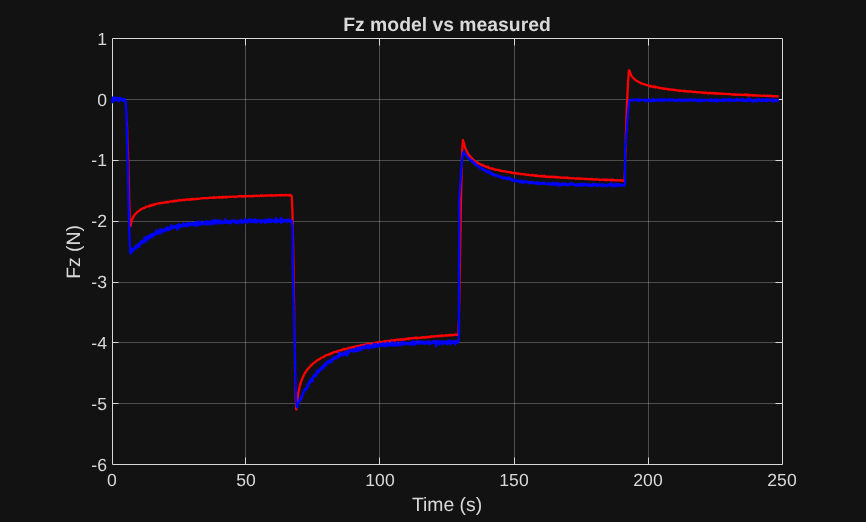

fz_1_fit = fz_1_e_fit + relaxation_component_model;
figure;
plot(t_ad,fz_1,"LineWidth",1.3,"Color","red");
hold on;
plot(t_ad, fz_1_fit,"LineWidth",1.3,"Color","blue");
grid on;
title("Fz model vs measured");
xlabel("Time (s)");
ylabel("Fz (N)");
hold off;

### Relaxation online estimation

vel_threshold = 5e-4

vel_threshold = 5.0000e-04


%%% Input
z_1; % using this, estimate the relaxation component online


%%% These are the lattice characteristic variables
k; % the elastic coeff
r1; % reducing relaxation coeff
r2; % steady state relaxation coeff
back_track = 0.1 % look back in history

back_track = 0.1000

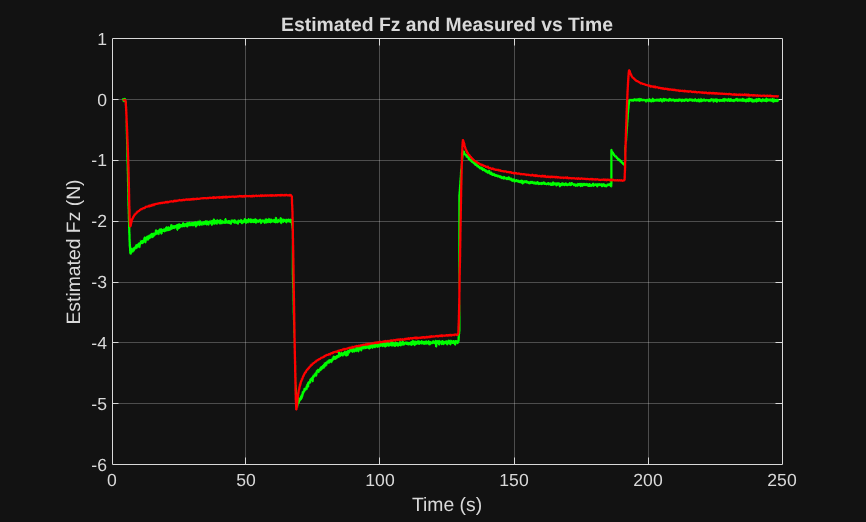

time_window = 10;


time_elapsed = 0.0;
last_time = 0.0;

fz_1_estimate = [];
dz = [];
signTerm = 1;

for i=1:length
    if i>=420
        dz(i-419) = (z_1(i) - z_1(i - (back_track*100)))/back_track; % avg vel over 0.1s
        if abs(dz(i-419)) > vel_threshold
            last_time = t_ad(i);
            signTerm = dz(i-419)/abs(dz(i-419));
        end
        time_elapsed = t_ad(i) - last_time;
        fz_1_estimate(i-419) = -(-k*z(i) + signTerm*(r1*z_1(i)*(exp(-time_elapsed/time_window)) + r2*z_1(i)));
    end
end

%%% Output
fz_1_estimate;

plot(t_ad(420:end), fz_1_estimate, 'LineWidth', 1.3, 'Color', 'green'); % Plot the estimated force
hold on;
plot(t_ad(420:end), fz_1(420:end), "LineWidth", 1.3, "Color", "red");
xlabel('Time (s)');
ylabel('Estimated Fz (N)');
title('Estimated Fz and Measured vs Time');
grid on;
hold off;

### Detect points of movement

v0 = 2.1e-4;

dz_1_filtered = lowpass(dz_1,0.00001);

dz_1_fitlered = dz_1_filtered(420:end);
ts = t_ad;


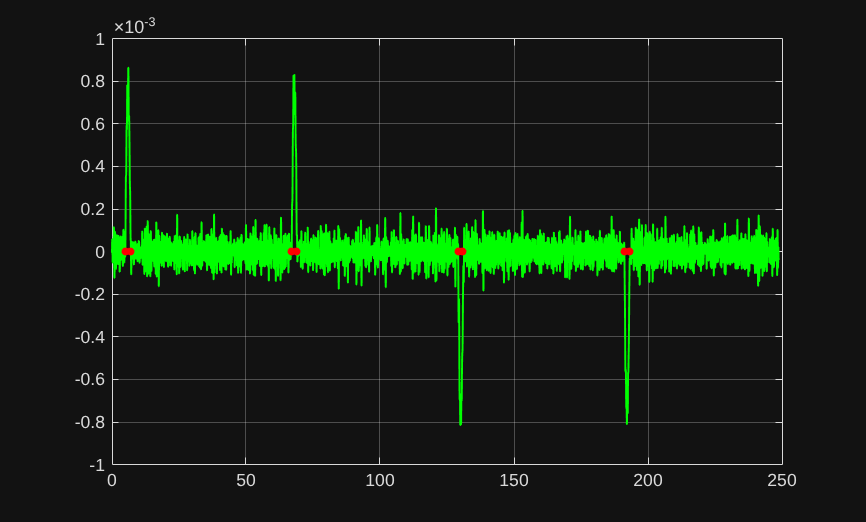


plot(ts,dz_1_filtered,"LineWidth",1.1,"Color","green");
hold on;
grid on;

ts_movs = [];
indices = [];
i = 1;
t_counter = 1;

length = size(dz_1_filtered,1);

while true
    if i>length
        break;
    end
    if abs(dz_1_filtered(i)) > v0
        ts_movs(t_counter) = ts(i-5);
        indices(t_counter) = i-5;
        t_counter = t_counter + 1;
        i = i + 5;
        while abs(dz_1_filtered(i)) > v0
            i = i+5;
        end
        ts_movs(t_counter) = ts(i-5);
        indices(t_counter) = i-5;
        t_counter = t_counter + 1;
        i = i+5;
    else
        i = i+5;
    end
end

ts_movs = ts_movs';
indices = indices';

n_movs = size(ts_movs,1);
scatter(ts_movs,zeros(n_movs),20,"red","filled");
hold off;